# **Third Optimal Control Project**

# **Design of an LQT controller Using Deviation Variables for a mass-spring-damper system.**

## Ali Eidizadeh                            ali80ei@gmail.com

## Amirhadi Keyvan     amirhadikeyvan@gmail.com

%% part C
clc 
clear 
close all
%---    system definition
m1 = 1;
m2 = 1;
c1 = 1;
c2 = 1;
k1 = 1;
k2 = 1;

A = [0              1               0       0;...
    -(k1+k2)/m1     -(c2+c1)/m1     k2/m1   c2/m1;...
    0               0               0       1;...
    k2/m2           c2/m2          -k2/m2  -c2/m2;]

A =      0     1     0     0
    -2    -2     1     1
     0     0     0     1
     1     1    -1    -1


B = [0;0;0;1/m2]

B =      0
     0
     0
     1


C = [1 0 0 0]

C =      1     0     0     0


D = 0

D = 0


%---    controllability analysis
rank(ctrb(A,B))

ans = 4

rank(obsv(A,C))

ans = 4


%---    LQR
Q = diag([100000 1 1 1]);
R = 0.0001;
K = lqr(A,B,Q,R)

K = 	1.0e+04 *

    3.1378    0.2567    0.0122    0.0123



%---    Deviation
B_pseudoinverse = pinv(B)

B_pseudoinverse =      0     0     0     1


F = -B_pseudoinverse*A

F =     -1    -1     1     1


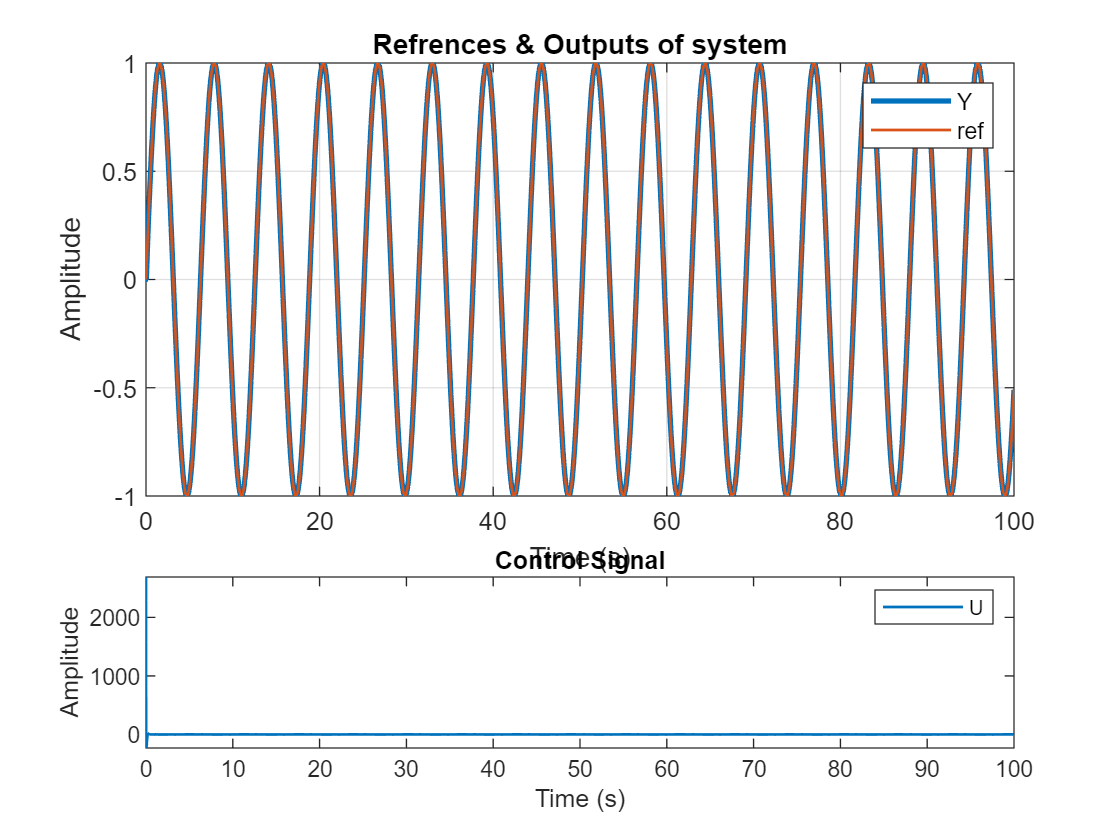


% Simulation of Closed Loop System
simOut = sim('Deviation');

% Plotting
figure
subplot(3,1,1:2)
plot(simOut.y,'linewidth',2)
hold on
plot(simOut.Ref1,'linewidth',1)
hold on
grid on
legend('Y','ref')
xlabel('Time (s)')
ylabel('Amplitude')
title('Refrences & Outputs of system')
subplot(3,1,3)
plot(simOut.U,'linewidth',1)
legend('U')
xlabel('Time (s)')
ylabel('Amplitude')
title('Control Signal')

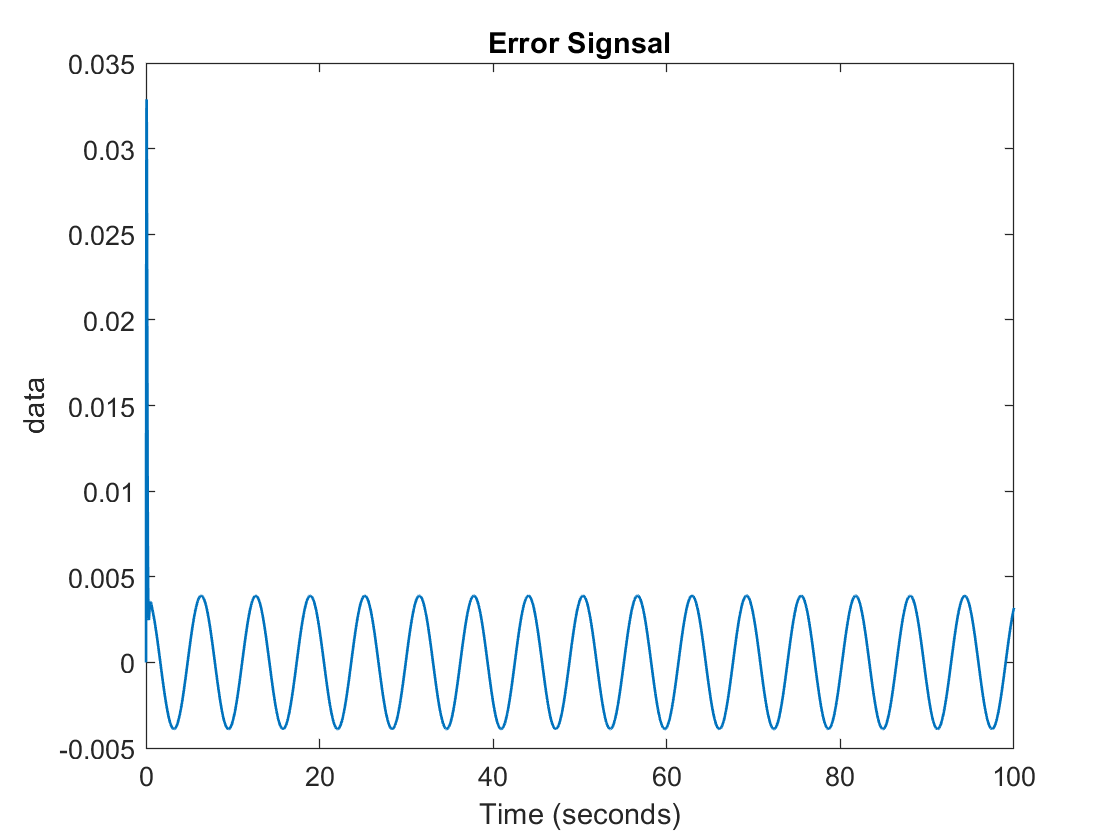


figure
plot(simOut.Error,'linewidth',1)
title('Error Signsal')